clc
clear
close all

% Order of ideal function
N = 3

N = 3


% Number of microphones M > N 
%M = N +3
M =7

M = 7


% Steering of main lobe
steerAng =138.01

steerAng = 138.0100

%xs = cosd(steerAng);
xs = sind(steerAng-90);

% Speed of sound (m/s)
%c = 343;  
c = 1496;


% Minimum and maximum frequency
f_min = 0;
f_max = 24e3;

% Signal frequency to design filter (Hz)
f = f_max; % (Invariant)

% Frequency sweep list
freqs = linspace(f_min, f_max, (f_max-f_min)/(100)+1);
freqs(1) = 20;

thetas = linspace(0,2*pi,360);

% Length of array (m)
dmax = 1;

(c./[4000/2 (4000+14000)/2 (14000+24000)/2])*0.1

ans =     0.0748    0.0166    0.0079


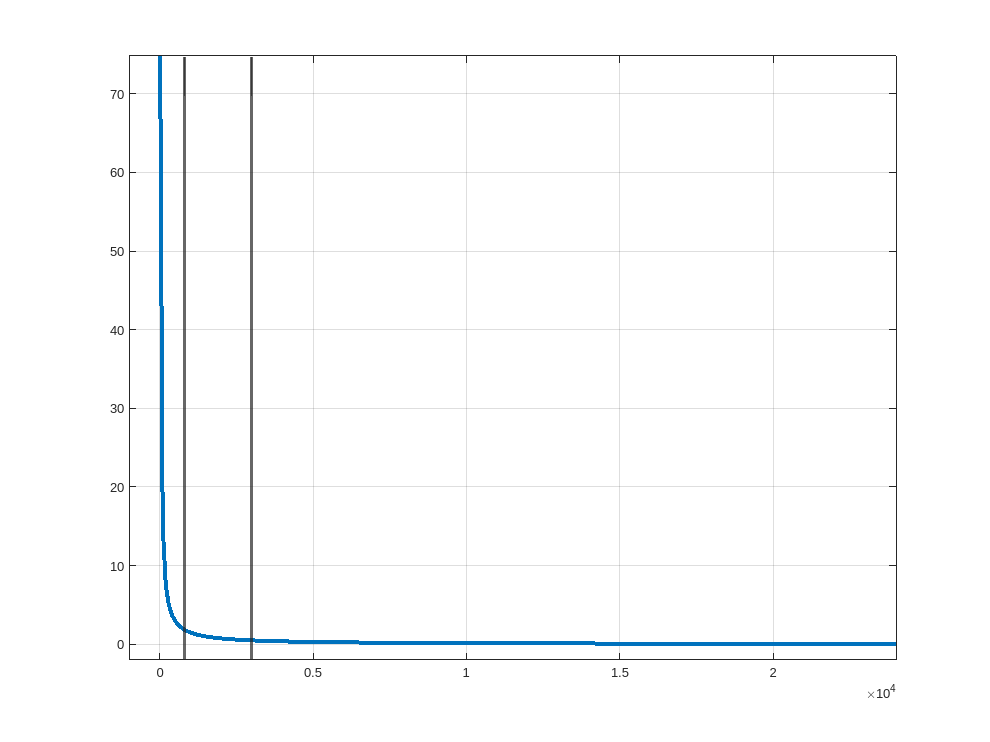

plot(freqs,c./freqs, 'LineWidth', 3)
hold on
%plot(ones(length(freqs),1)*1000, linspace(0,c/max(freqs),length(freqs)))
xline(800, 'LineWidth', 2)
xlim([-1000 max(freqs)])
ylim([-2 c/min(freqs)])
xline(3000, 'LineWidth', 2)
grid
hold off


% ULA1Lambda = c/400 % en hel bølgelængde over 3 mikrofoner
% ULA2Lambda = c/1100
% ULA3Lambda = c/10500
% 
% divfactor = 4;
% ULA1 = (0:2).*ULA1Lambda*1/divfactor% en hel bølgelængde over 3 mikrofoner
% ULA2 = [ULA1(2)-ULA2Lambda/divfactor ULA1(2) ULA1(2)+ULA2Lambda/divfactor]
% ULA3 = [ULA1(2)-ULA3Lambda/divfactor ULA1(2) ULA1(2)+ULA3Lambda/divfactor]


ULA1 = linspace(0, dmax, N)

ULA1 =          0    0.5000    1.0000


%ULA1 = (0:2).*0.6
ULA1Offset = ULA1;
%ULA2 = [dmax/2-dmax/4 dmax/2 dmax/2+dmax/4]
ULA2 = [ULA1(2)-ULA1(2)/4 ULA1(2) ULA1(2)+ULA1(2)/4]

ULA2 =     0.3750    0.5000    0.6250


ULA2Offset = ULA2-ULA2(1)

ULA2Offset =          0    0.1250    0.2500


%ULA3 = [dmax/2-dmax/14 dmax/2 dmax/2+dmax/14]
ULA3 = [ULA1(2)-ULA1(2)/12 ULA1(2) ULA1(2)+ULA1(2)/12]

ULA3 =     0.4583    0.5000    0.5417


%ULA3 = [0.7 0.75 0.8 0.85]
ULA3Offset = ULA3-ULA3(1)

ULA3Offset =          0    0.0417    0.0833



micArray = sort(unique([ULA1 ULA2 ULA3]))

micArray =          0    0.3750    0.4583    0.5000    0.5417    0.6250    1.0000


plot(micArray, zeros(length(micArray),1), 'o')


%tauULA1 = (micArray([1 ceil(end/2) end])*xs)/c;
tauULA1 = (ULA1Offset*xs)/c;
%tauULA2 = (micArray([2 ceil(end/2) end-1])*xs)/c;
tauULA2 = (ULA2Offset*xs)/c;
%tauULA3 = (micArray([3 ceil(end/2) end-2])*xs)/c;
tauULA3 = (ULA3Offset*xs)/c;

save('DASParams.mat', 'steerAng', 'micArray', 'tauULA1', 'tauULA2', 'tauULA3')

output = zeros(length(freqs),length(thetas));
for b=1:length(freqs)
    %for q=1:length(thetas)
        if freqs(b) < 1700
            outputEach = exp(-1i*2*pi*freqs(b)*(ULA1Offset.*cos(thetas(:))/c+tauULA1));
        elseif freqs(b) < 4000
            outputEach = exp(-1i*2*pi*freqs(b)*(ULA2Offset.*cos(thetas(:))/c+tauULA2));
        else
            outputEach = exp(-1i*2*pi*freqs(b)*(ULA3Offset.*cos(thetas(:))/c+tauULA3));
        end
    %end
    output(b,:) = sum(outputEach,2);
end

%bp = abs(output);
bp = sqrt(power(real(output),2)+power(imag(output),2))/N

bp =     0.9982    0.9982    0.9982    0.9982    0.9982    0.9982    0.9982    0.9982    0.9982    0.9982    0.9982    0.9983    0.9983    0.9983    0.9983    0.9983    0.9983    0.9983    0.9983    0.9983    0.9983    0.9983    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9985    0.9985    0.9985    0.9985    0.9985    0.9985    0.9986    0.9986    0.9986    0.9986    0.9986    0.9987    0.9987    0.9987    0.9987    0.9987    0.9988    0.9988    0.9988    0.9988    0.9989
    0.9558    0.9558    0.9559    0.9559    0.9559    0.9560    0.9561    0.9562    0.9563    0.9564    0.9566    0.9567    0.9569    0.9571    0.9573    0.9575    0.9578    0.9580    0.9583    0.9585    0.9588    0.9591    0.9594    0.9597    0.9601    0.9604    0.9608    0.9612    0.9615    0.9619    0.9623    0.9627    0.9632    0.9636    0.9640    0.9645    0.9649    0.9654    0.9659    0.9664    0.9668    0.9673    0.9678    0.9684    0.9689    0.9694    0.9699    0.9704    0.9710    

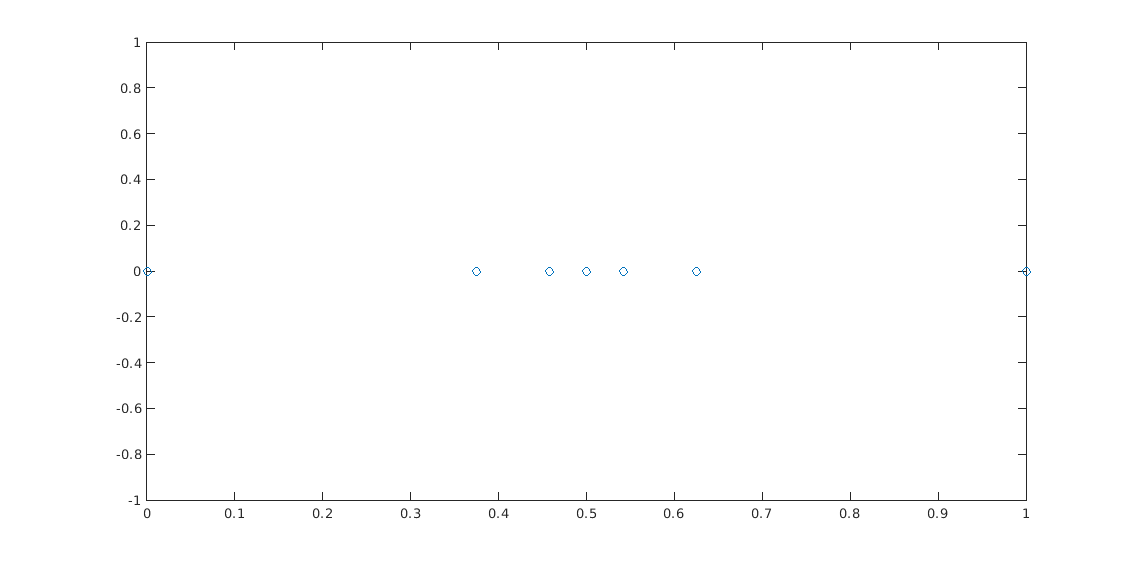

mindB = -50;
logOutput = mag2db(bp);
logOutput(logOutput < mindB) = mindB;

indexHz = find(freqs==9000); % Find design frequency in sweep list
plotVisibility = 'on';

figure(1)
set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
          'OuterPosition', [0 0 30 20]) %21/2-2*2

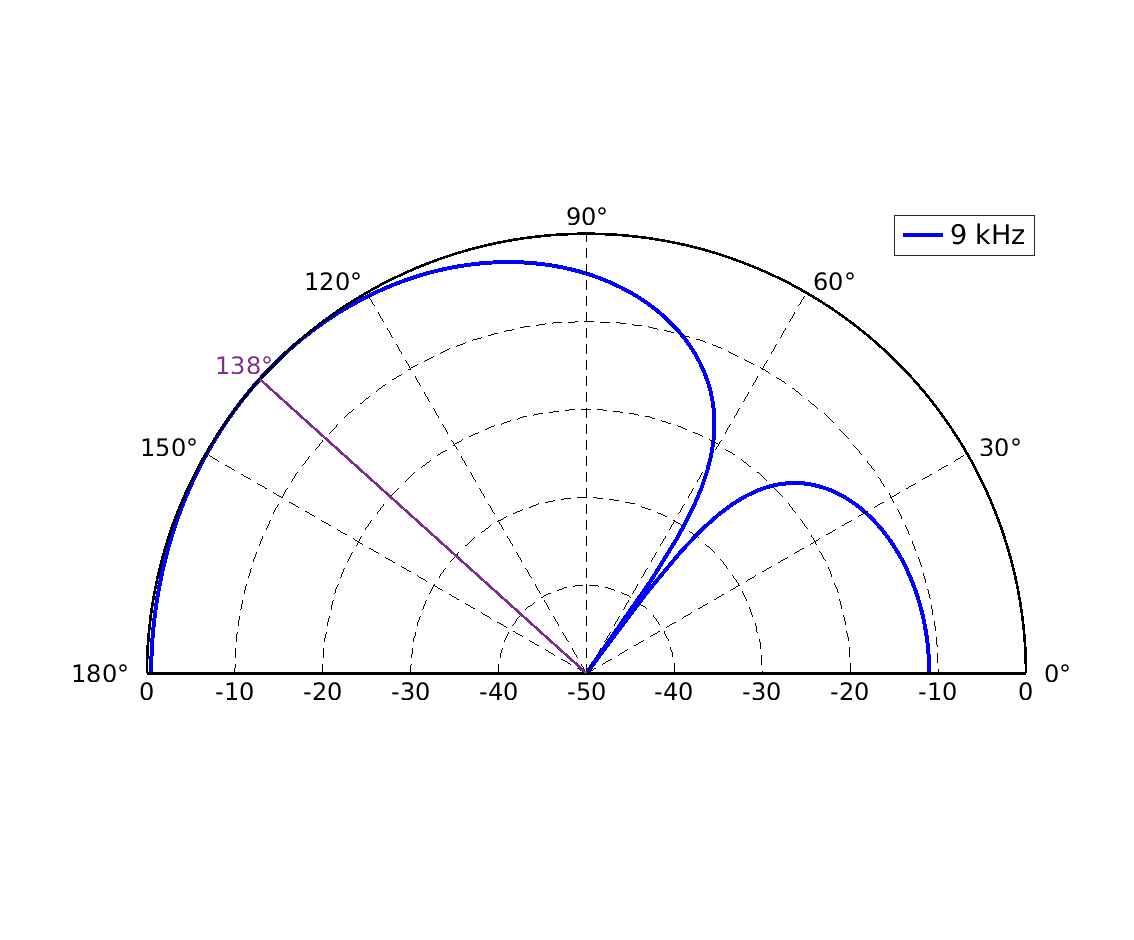

circPlot(freqs(indexHz), thetas, logOutput(indexHz,:), steerAng)

figure(2)
set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
          'OuterPosition', [0 0 30 30])

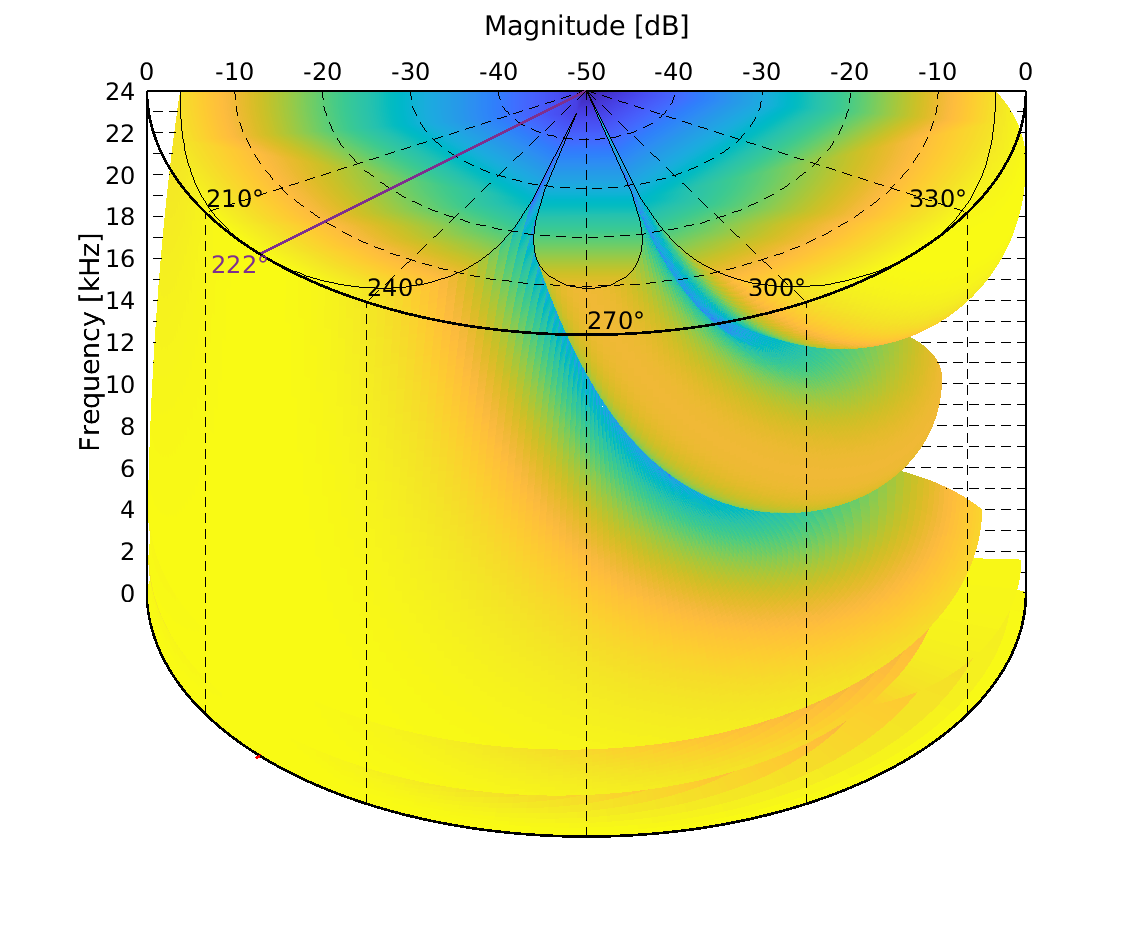

cylindricalPlot(freqs, thetas, logOutput, steerAng)